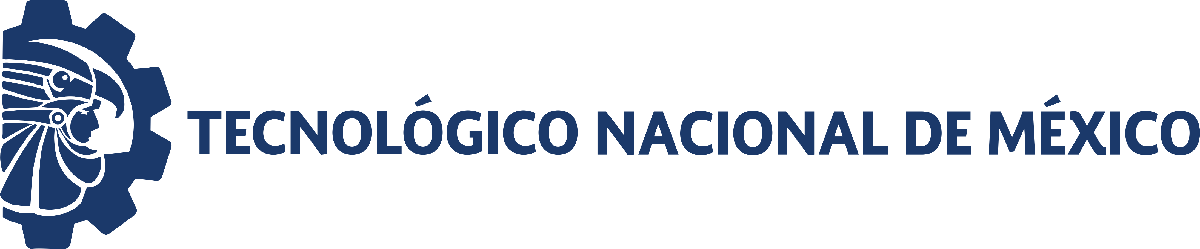                                 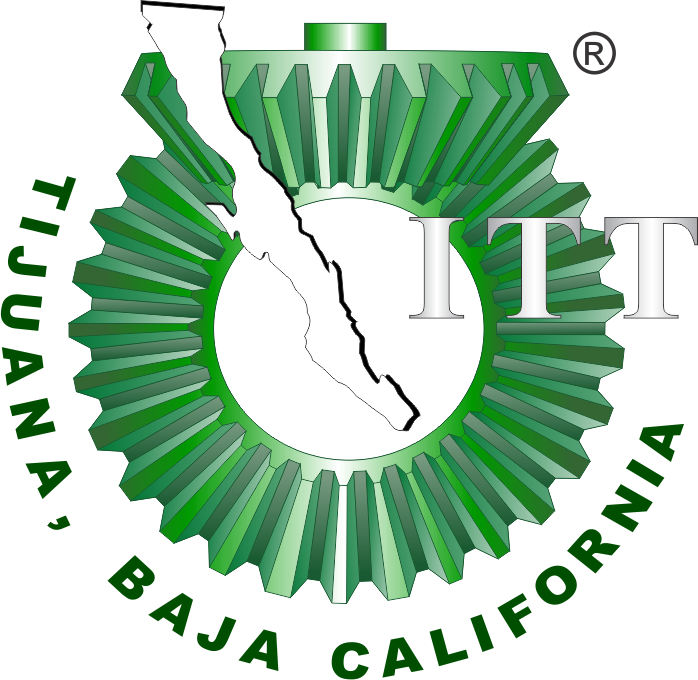

# Práctica 2: Sistema presa-depredador de Lotka-Volterra

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

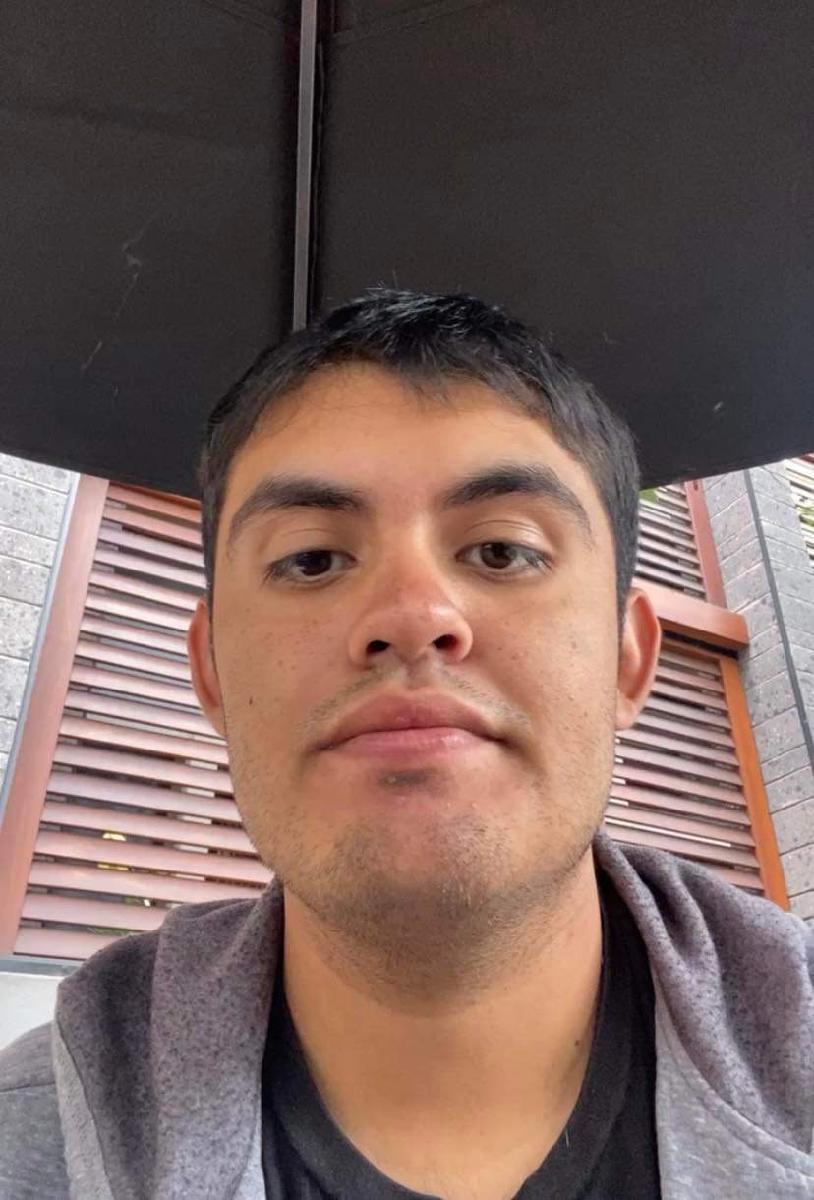

Nombre del alumno: **Andres Martin Bañuelos Elias**

Número de control: **21212142**

Correo institucional: **l21212142@tectijuana.edu.mx**

Carrera:** Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

**Objetivo: **Solucionar las ecuaciones de Lotka-Volterra para estudiar e ilustrar su dinámica en series de tiempo y en el plano de fase. El sistema presa-depredador se formula mediante las siguientes EDOs de primer orden.


$$\begin{array}{l}
\overset{\ldotp }{X} =\alpha x-\beta x\gamma \\
\overset{\ldotp }{Y} =\delta \textrm{xy}-\textrm{xy}
\end{array}$$


Con los valores de los parámetros $\alpha =0\ldotp 5,\;\delta =0\ldotp 001,\;\gamma =0\ldotp 2$ y las condiciones iniciales x(0)=75 y y(0)=75

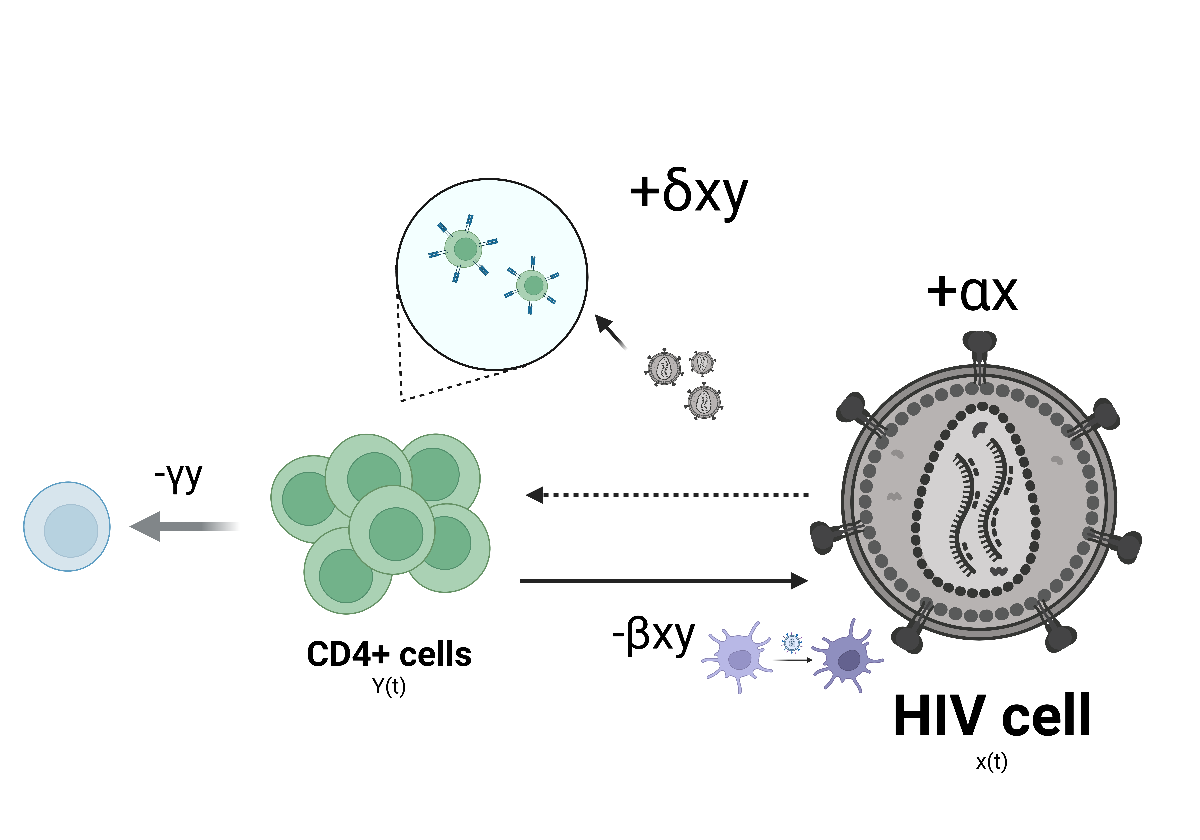

Figure represents a mathematical model of the interaction between CD4+ cells and the HIV virus. It shows that CD4+ cells Y(t) are infected by the HIV virus X(t) through a process represented by the rate −βxy. Once infected, the cells release new viral particles at a rate +$\delta \textrm{xy}$ contributing to the spread of the virus. Additionally, the virus replicates at a rate +αx,while CD4+ cells can naturally die at a rate −$\gamma y$.

## Simulation Data

clc; clear; close all; warning('off','all')

## Parameters and initial conditions

alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
P= [alpha,beta,delta,gamma];
x0=75; y0=75; tend=100;

## Solution by Euler's method

%dt = [2, 1, 0.5, 0.25, 1E-1, 1E-2, 1E-3, 1E-4, 1E-5, 1E-6];
dt=1E-4;
for i = 1:numel(dt)
    [t, x, y] = sys_Euler(x0, y0, dt(i), tend, P);  
   % plotEDOs(t, x, y, P, dt(i), 'Euler') 
    exportgraphics(gcf, ['Lotka-Volterra_Euler' num2str(dt(i)) '.PNG'], 'ContentType', 'vector')
end

## Solution by Heun's method

dt=1E-1;
for i = 1:numel(dt)
    [t, x, y] = sys_Heun(x0, y0, dt(i), tend, P);  
   % plotEDOs(t, x, y, P, dt(i), 'Heun') 
    exportgraphics(gcf, ['Lotka-Volterra_Heun' num2str(dt(i)) '.PNG'], 'ContentType', 'vector')
end

## Simulink

file = 'SistemaUchiha';
sim(file);
parameters.StopTime = '100';
parameters.Solver = 'ode15s';

## Solution by Order15s [Stiff Solver]

parameters.Solver = 'ode15s';
s15s = sim(file,parameters);
%plotEDOs(s15s.t,s15s.x,s15s.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode15s.pdf'],'ContentType','vector')

## Solution by Order23s [Stiff Solver]

parameters.Solver = 'ode23s';
s23s = sim(file,parameters);
%plotEDOs(s23s.t,s23s.x,s23s.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23s.pdf'],'ContentType','vector')

## Solution by Order23t [Stiff Solver]

parameters.Solver = 'ode23t';
s23t = sim(file,parameters);
%plotEDOs(s23t.t,s23t.x,s23t.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23t.pdf'],'ContentType','vector')

## Solution by Order23tb [Stiff Solver]

parameters.Solver = 'ode23tb';
s23tb = sim(file,parameters);
%plotEDOs(s23tb.t,s23tb.x,s23tb.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23tb.pdf'],'ContentType','vector')

## Solution by Order45 [Nonstiff Solver]

parameters.Solver = 'ode45';
s45 = sim(file,parameters);
%plotEDOs(s45.t,s45.x,s45.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode45.pdf'],'ContentType','vector')

## Solution by Order23 [Nonstiff Solver]

parameters.Solver = 'ode23';
s23 = sim(file,parameters);
%plotEDOs(s23.t,s23.x,s23.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23.pdf'],'ContentType','vector')

## Solution by Order113 [Nonstiff Solver]

parameters.Solver = 'ode113';
s113 = sim(file,parameters);
%plotEDOs(s113.t,s113.x,s113.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode113.pdf'],'ContentType','vector')

Based on numerical simulations, it is concluded that the Lotka-Volterra system exhibits stiffness, making it necessary to use a nonstiff solver to ensure accuracy and stability. 

Nonstiff solvers are essential to avoid instability and ensure the precision and efficiency of the results. Using an inappropriate solver can lead to numerical instability or excessive computation time, emphasizing the importance of selecting the right method for efficient and reliable results.

**Reference: **

[1] A. Garfinkel, J. Shevtsov, and Y. Guo, Modeling Life: The Mathematics of Biological Systems, 1st ed. Cham, Switzerland: Springer, 2017, ch. 1, sec. 1.1–1.3, pp. 1–18.

[2] F. L. Biafore and C. E. D’Attellis, "Exact Linearisation and Control of a HIV-1 Predator-Prey Model," in *Proceedings of the 27th Annual International Conference of the IEEE Engineering in Medicine and Biology Society (EMBC)*, Shanghai, China, Sep. 2005, pp. 2367-2370.

[3] J. D. Murray, *Mathematical Biology: I. An Introduction*, 3rd ed. New York, NY, USA: Springer, 2002, ch. 2, pp. 25–60.

[4] L. Edelstein-Keshet, *Mathematical Models in Biology*, Philadelphia, PA, USA: SIAM, 2005, ch. 3, sec. 3.1–3.4, pp. 75–110.

[5] H. G. Othmer, F. R. Adler, and M. A. Lewis, *Applied Mathematical Models in Human Physiology*, Philadelphia, PA, USA: SIAM, 2007, ch. 5, pp. 150–185.

## Equilibrium poitns

clc; clear; close all; warning('off','all')

alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
P= [alpha,beta,delta,gamma];
x0=75; y0=75; tend=100;
dt=1E-4;
    [t, x, y] = sys_Heun(x0, y0, dt, tend, P);
  %  plotEDOs(t, x, y, P, dt); ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
       % exportgraphics(gcf, ['Lotka-Volterra_Equilibria.pdf'], 'ContentType', 'vector')

## Equilibrium points and Jacobian matrix

clc; clear;close all; warning('off','all')
syms x y alpha beta delta gamma
dx = alpha*x - beta*x*y;
dy = delta*x*y - gamma*y;
J = jacobian([dx dy],[x y]);
%fprintf('Jacobian matrix of the Lotka-Volterra system :'); disp(J)
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
Edos = solve([dx dy],[x y]);
%fprintf(['The Lokta-Volterra system has  ', num2str(length(Edos.x)) , 'Equlibrium points.'])
X0=Edos.x(1); Y0=Edos.y(1);
X1=Edos.x(2); Y1=Edos.y(2);
syms x0 x1 y0 y1
%fprintf('Equilibrium Poins of the Lotka-Volterra system: ');...
   % disp([x0 y0 X0 Y0]); disp([x1 y1 X1 Y1])
clear alpha beta delta gamma
alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
%disp('(x0,y0)=(0,0)'); disp(['(x1, y1) = (' num2str(gamma/delta) ',' num2str(alpha/beta) ')'])

## Local estability

clc; clear;
alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
syms  x y
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1));
y0 = double(edos.y(1));
x1 = double(edos.x(2));
y1 = double(edos.y(2));
clear x y
x = [x0; x1]; 
y = [y0; y1];
var = {'(x0,y0)';'(x1,y1)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
%fprintf('Equilibrium Poins of the Lotka-Volterra system: \n'); disp(Equilibria)
clc; clear;
alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
syms  x y
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
clear x y
x = [x0; x1]; 
y = [y0; y1];
var = {'(x0,y0)';'(x1,y1)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
%fprintf('Equilibrium Poins of the Lotka-Volterra system: \n'); disp(Equilibria)
L = zeros(length(x), length(x));
for i = 1:length(x)
    J = [alpha - beta*y(i), -beta*x(i); 
         delta*y(i), delta*x(i) - gamma];
  L(i,:) = eig(J).'; 
end
L1 = L(:,1); 
L2 = L(:,2);
Lambdas = table(L1, L2, 'RowNames', var);
%disp('Eigenvalues of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

The analysis of the eigenvalues of the Jacobian matrix indicates that the equilibrium point L1 is unstable since it has an eigenvalue with a positive real part, causing any perturbation to drive the system away from this point over time. On the other hand, the equilibrium point L2 behaves as a center, given that its eigenvalues are purely imaginary, which implies sustained oscillations without damping, but without the solutions diverging or converging.

## Data fitting

clc; clear;close all; warning('off','all')

## Raw data

sys = readmatrix('data.csv');
to = sys(:,1); to = floor(to); to(1) = 0;
xo = sys(:,2);
yo = sys(:,3);
alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
P= [alpha,beta,delta,gamma];

## Smooth data

xo=smoothdata(xo,'gaussian',5);
yo=smoothdata(yo,'gaussian',5);
 plotEDOs_fit(to, xo, yo, P,0); ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data fitting-Lotka-Volterra.pdf'], 'ContentType', 'vector')

## Fit data

P0 = [1;0.001;0.001;0.1];
mdl = Variant(to,xo,yo,P0);

t-Studen value: 2.0129
 

Sample size (n): 25
Parameters to be estimated (pars): 4
Degrees of freedom: 46
Significance level (alpha): 0.05
-Student value: 2.0129
Adjusted R-squared: 0.9916
Corrected AIC (n/pars<40) : 198.6034
    Parameters    Estimate         SE           MoE                 CI95               Pvalue  
    __________    _________    __________    __________    ______________________    __________

      alpha         0.42248     0.0077039      0.015507      0.40697      0.43798    1.4621e-43
      beta         0.008872    0.00019134    0.00038515    0.0084869    0.0092572    2.8747e-40
      delta       0.0052884    0.00011176    0.00022496    0.0050635    0.0055134    1.1513e-40
      gamma         0.21733     0.0047274     0.0095158      0.20781      0.22684    4.23

fa=mdl.Fitted;
fx=reshape(fa,[],2);
xa=fx(:,1);ya=fx(:,2);
P=table2array(mdl.Coefficients(:,1));
fa=mdl.Fitted;
fx=reshape(fa,[],2);
xa=fx(:,1);ya=fx(:,2);
P=table2array(mdl.Coefficients(:,1));
%plotResults(to,[xo,xa],[yo,ya],P);
 %ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data FIT.pdf'], 'ContentType', 'vector')

## Simulation Data HIV

## Data fitting HIV

clc; clear;close all; warning('off','all')

## Raw data HIV

sys = readmatrix('datos8.csv');
to = sys(:,1); to = floor(to); to(1) = 0;
xo = sys(:,2);
yo = sys(:,3);
alpha=0.5; beta= 0.01; delta=0.001; gamma=0.2; 
P= [alpha,beta,delta,gamma];

## Smooth data HIV

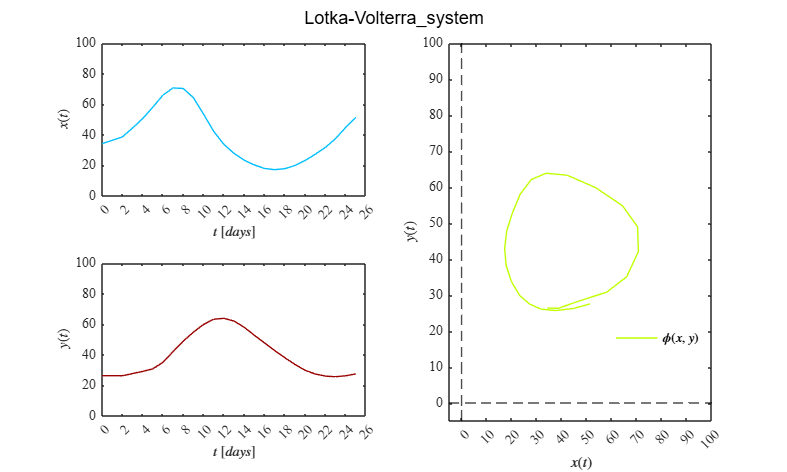

xo=smoothdata(xo,'gaussian',5);
yo=smoothdata(yo,'gaussian',5);
 plotEDOs_fit(to, xo, yo, P,0); ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data fitting-Lotka-Volterra.pdf'], 'ContentType', 'vector')

## Fit data HIV

P0 = [1;0.001;0.001;0.1];
mdl = Variant(to,xo,yo,P0);fa=mdl.Fitted;

t-Studen value: 2.0129
 

Sample size (n): 25
Parameters to be estimated (pars): 4
Degrees of freedom: 46
Significance level (alpha): 0.05
-Student value: 2.0129
Adjusted R-squared: 0.9652
Corrected AIC (n/pars<40) : 253.2016
    Parameters    Estimate         SE           MoE                 CI95               Pvalue  
    __________    _________    __________    __________    ______________________    __________

      alpha         0.34901      0.013308      0.026787      0.32222      0.37579    2.6094e-29
      beta        0.0083106    0.00036851    0.00074177    0.0075688    0.0090523    1.6527e-26
      delta       0.0056485    0.00025735    0.00051802    0.0051305    0.0061666     5.184e-26
      gamma         0.23325      0.010928      0.021997      0.21126      0.25525    1.67

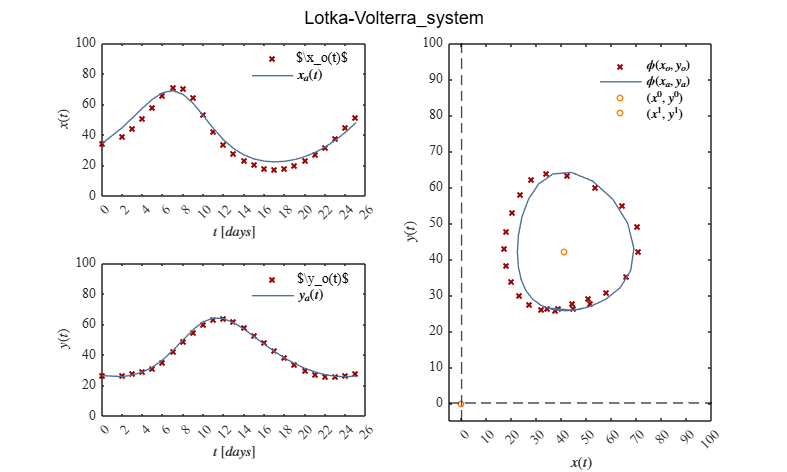

fx=reshape(fa,[],2);
xa=fx(:,1);ya=fx(:,2);
P=table2array(mdl.Coefficients(:,1));
fa=mdl.Fitted;
fx=reshape(fa,[],2);
xa=fx(:,1);ya=fx(:,2);
P=table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P);
 ttl = 'Lotka-Volterra_system'; sgtitle(ttl,'Interpreter','latex')
        exportgraphics(gcf, ['Data FIT.pdf'], 'ContentType', 'vector')

## Functions

## Euler's method

function [t, x, y] = sys_Euler(x0, y0, dt, tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend / dt);
    t = (0:dt:tend)';
    
    x = zeros(length(t), 1); x(1) = x0;
    y = zeros(length(t), 1); y(1) = y0;

    for i = 1:n
        x(i+1) = x(i)+dt*(alpha*x(i)-beta*x(i)*y(i));
        y(i+1) = y(i)+dt*(delta*x(i)*y(i)-gamma*y(i));
    end
end

## Heun's method

function [t,x,y] = sys_Heun(x0,y0,dt,tend,P)
 alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
 n = round(tend/dt);
 t = (0:dt:tend);
 x = zeros(length(t),1); x(1) = x0;
 y = zeros(length(t),1); y(1) = y0;

 for i = 1:n
    [fx,fy] = f(x(i),y(i));
    xn = x(i) + fx*dt;
    yn = y(i) + fy*dt;
    [fxn,fyn] = f(xn,yn);

    x(i+1) = x(i) + (fx + fxn)*dt/2;
    y(i+1) = y(i) + (fy + fyn)*dt/2;
 end

    function [dx,dy] = f(x,y)
    dx = alpha*x-beta*x*y;
    dy = delta*x*y-gamma*y;
    end
end

## Solutions and trajectories

function plotEDOs(t, x, y, P, dt, method)
    set(figure(), 'Color', 'w')
   Mecambiareaindustrial = [
    0.60, 0.00, 0.00;  
    0.75, 1.00, 0.00;  
    0.00, 0.75, 1.00;  
    0.50, 0.00, 0.75;  
    1.00, 0.50, 0.00;  
    0.40, 0.20, 0.10;  
    1.00, 0.00, 0.80;  
    1.00, 0.50, 0.75;  
    0.00, 0.85, 0.65;  
    0.30, 0.45, 0.60   
];  
rng('shuffle');  
    indices = randperm(size(Mecambiareaindustrial,1), 3); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);

    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 20, 12])

    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(t, x, '-', 'LineWidth', 1, 'Color', c1)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$x(t)$', 'Interpreter', 'latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 600]); yticks(0:100:600)

    subplot(2,2,3)
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(t, y, '-', 'LineWidth', 1, 'Color', c2)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$y(t)$', 'Interpreter', 'latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); yticks(0:20:100)

  subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off
    plot(x,y,'-','LineWidth',1,'Color',[0.50, 0.00, 0.75])
    plot(x(1),y(1),'o','MarkerSize',4,'LineWidth',1,'Color',[0.60, 0.00, 0.00])
    plot(0,0,'x','MarkerSize',5,'LineWidth',1,'Color',[ 0.00, 0.85, 0.65])
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'Color',[1.00, 0.50, 0.75])
    xlabel('$x(t)$', 'Interpreter','latex')
    ylabel('$y(t)$', 'Interpreter','latex')
    xlim([-60 600]); xticks(0:100:600)
    ylim([-5 100]); yticks(0:20:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

L = legend('$\phi(x,y)$', '$(x(0),y(0))$', '$(x^_0,y^_0)$','$(x^_1,y^_1)$');
set(L, 'Interpreter', 'Latex', 'Location', 'none', 'Position', [0.778, 0.263, 0.115, 0.041], 'Box', 'Off')
if dt == 0
        ttl = ['Lotka-Volterra System'];
        sgtitle(ttl,'Interpreter','Latex');
    else
        ttl = ['Step size: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','Latex');
end
end


%Data Fitting
function plotEDOs_fit(t,x,y,P,dt)
    set(figure(),'Color','w')
    Mecambiareaindustrial = [
    0.60, 0.00, 0.00;  
    0.75, 1.00, 0.00;  
    0.00, 0.75, 1.00;  
    0.50, 0.00, 0.75;  
    1.00, 0.50, 0.00;  
    0.40, 0.20, 0.10;  
    1.00, 0.00, 0.80;  
    1.00, 0.50, 0.75;  
    0.00, 0.85, 0.65;  
    0.30, 0.45, 0.60   
];  
rng('shuffle');  
indices = randperm(size(Mecambiareaindustrial,1), 3); 
c1 = Mecambiareaindustrial(indices(1), :);
c2 = Mecambiareaindustrial(indices(2), :);
c3 = Mecambiareaindustrial(indices(3), :);
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)  
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 26]); xticks(0:2:26)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)  
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 26]); xticks(0:2:26)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',c3)  
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$');
    set(L,'Interpreter','Latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','Off')
    
    if dt == 0
        ttl = 'Lotka-Volterra System';
        sgtitle(ttl,'Interpreter','Latex');
    else
        ttl = ['Step size: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','Latex');
    end
end



## Nonlinear regression algorithm

function mdl= Variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-1;
        t = reshape (t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = alpha*x-beta*x*y;
            dy = delta*x*y-gamma*y;
        end 
        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha=0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE; 
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['alpha';'beta ';'delta';'gamma'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    disp(['t-Studen value: ',num2str(tval)])
    disp(' ')
    
    fprintf('\nSample size (n): %d', numel(xo))
    fprintf('\nParameters to be estimated (pars): %d', numel(P0))
    fprintf('\nDegrees of freedom: %d', dof)
    fprintf('\nSignificance level (alpha): %.2f', alpha)
    fprintf('\n-Student value: %.4f', tval)
    fprintf('\nAdjusted R-squared: %.4f', mdl.Rsquared.Adjusted)
    fprintf('\nCorrected AIC (n/pars<40) : %.4f\n', mdl.ModelCriterion.AICc)
    
    disp(Results)
end 
%Plotresults
function plotResults(t,x,y,P,dt)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;  
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.50, 0.75;  
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];  
    rng('shuffle');  
    indices = randperm(size(Mecambiareaindustrial,1), 3); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,x(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 26]); xticks(0:2:26)
    ylim([0 100]); yticks(0:20:100)
    L = legend('$\x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 26]); xticks(0:2:26)
    ylim([0 100]); yticks(0:20:100)
    L = legend('$\y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1) 
    plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',c2) 
    plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',c3) 
    plot(gamma/delta,alpha/beta,'o','MarkerSize',4,'LineWidth',1,'Color',c3)

    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')

    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 100]); yticks(0:10:100)

    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend ('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^0,y^0)$','$(x^1,y^1)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
end